Design of a Universal LQG Controller for Coupled Tanks Using Variable Scaling 

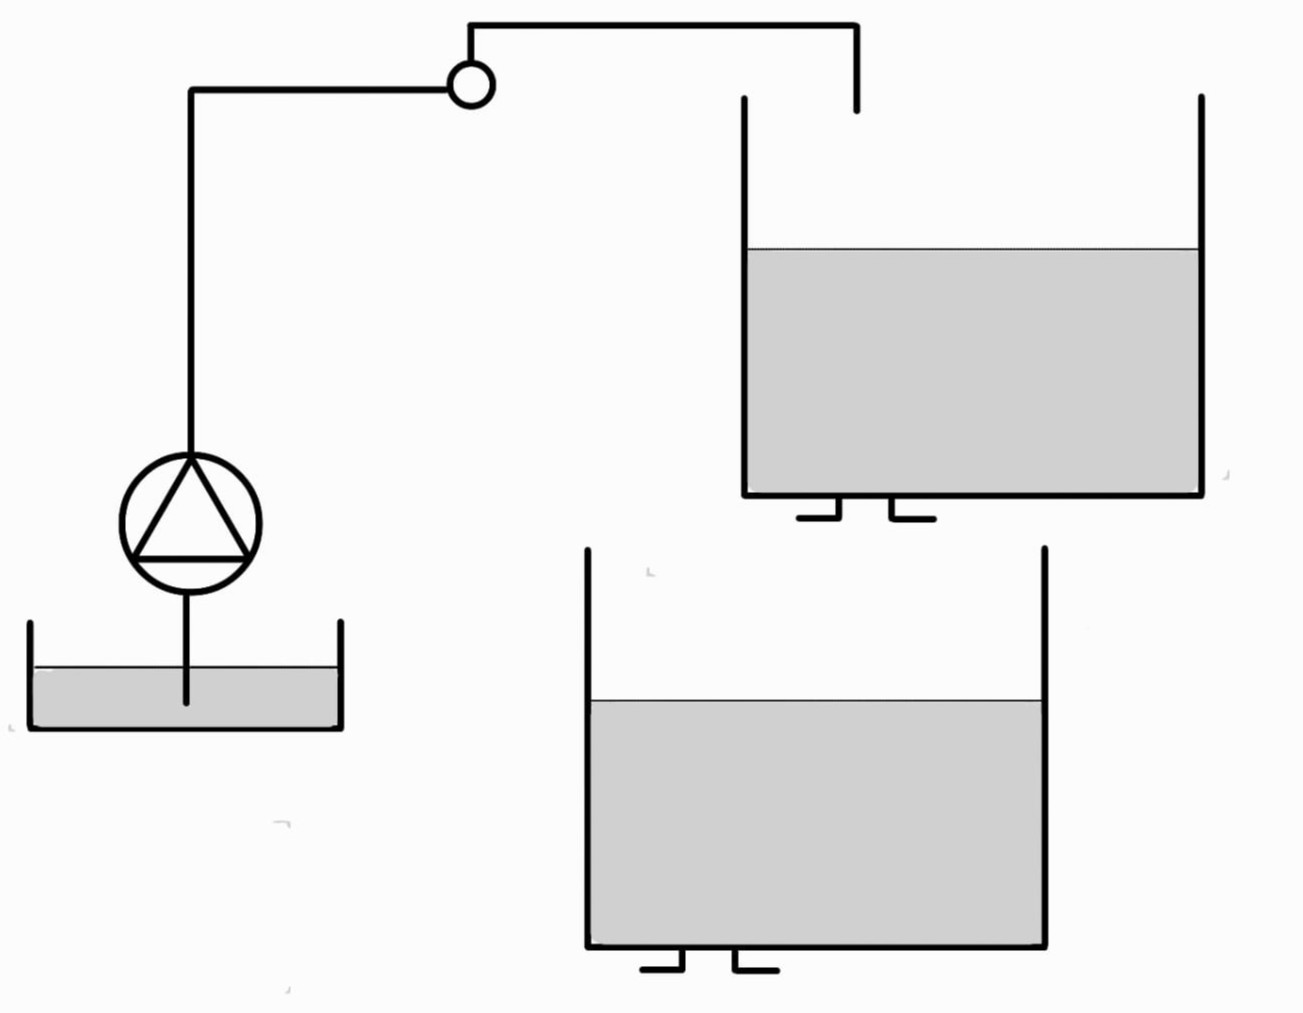

PARÁMETROS DEL TANQUE :

TANQUE 1 :

Diametro del tanque 1 en metros :

dt1 =2; At1 = pi*dt1^2/4;

Area de salida del tanque 1 en metros :

A01 =0.0209;

TANQUE 2 :

Diametro del tanque en metros :

dt2=2; At2 = pi*dt2^2/4;

Area de salida del tanque 1 en metros :

A02 =0.0231;

Pump Flow Constant $\frac{m^3 }{\textrm{sV}}$

Kp = 0.025;  b = Kp/At2;

Grevedad

g = 9.8;


$$\frac{\mathrm{d}}{\mathrm{d}t}h_{2\;\;} =b\cdot u\left(t\right)-a_2 \sqrt{h_{2\;\;} }$$
      
$$\frac{\mathrm{d}}{\mathrm{d}t}h_{1\;\;} =a_{2\;\;\;} \sqrt{h_{2\;\;} }{-\;\;a}_1$$

$$\sqrt{h_{1\;\;} }$$


a2 = (A02*sqrt(2*g)) / At2;   a1 = (A01*sqrt(2*g)) / At1;

PUNTO DE EQUILIBRIO EN  $\frac{\mathrm{d}}{\mathrm{d}t}h_{2\;\;} =$$\frac{\mathrm{d}}{\;\mathrm{d}t}h_{1\;\;} =0$  ;  se elije una altura fija para el tanque 1

(punto donde debe estabilizarse)

l1 = 1.5

l1 = 1.5000

l2 = ((a1*sqrt(l1))/a2)^2

l2 = 1.2279



Veq = ((a2*sqrt(l2))/b)

Veq = 4.5329


x1e = l1;x2e = l2;


l11=l1*(1/0.3)

l11 = 5

l22=l2*(1/0.3)

l22 = 4.0930

LINEALIZACIÓN

s1 = sqrt(x1e);
s2 = sqrt(x2e);

A = [ -a1/(2*s1),  a2/(2*s2);
       0        , -a2/(2*s2) ];

B = [0;
     b];

C = eye(2);
D = [0;0];

Xeq = [l1;
     l2]

Xeq =     1.5000
    1.2279


 DISEÑO DE LQR

Q = [1000 0;  
     0 1];  
R = 1;
K = lqr(A,B,Q,R)   

K =    23.8055    7.7609


FILTRO DE KALMAN 

Qk = [100 0;  
      0  1];     
Rk = [1 0;    
      0 1];       
G = eye(2);
L = lqe(A, G, C, Qk, Rk)

L =     9.9880    0.0013
    0.0013    0.9854



Ac = A - B*K - L*C  

Ac =   -10.0000    0.0134
   -0.1908   -1.0619


Bc = L               

Bc =     9.9880    0.0013
    0.0013    0.9854


Cc = -K             

Cc =   -23.8055   -7.7609


Dc = zeros(size(K,1), size(C,1))  

Dc =      0     0
